% Main File to generate Combined Action Potential (AP) Morphology Analysis
% Replicates logic from FINAL_OverlayPlot_Calcium_v2 but for Voltage (Vm)
close all; clear; clc;

% Load initial conditions and the original baseline parameters
load ICs_baseline;
load baseline_parameter_inputs;

% Store a clean copy of the baseline parameters
original_baseline_params = baseline_parameter_inputs;

% ========================================================================
%  START: BATCH SIMULATION BLOCK
% ========================================================================

num_models = 5;
% Storage for traces
all_time_ap = cell(1, num_models);
all_vm = cell(1, num_models);

% Storage for scalar stats (Rows: Models, Cols: Parameters)
stats_matrix = zeros(num_models, 7);

model_legends = cell(1, num_models);

% --- Loop through each model from 0 (Baseline) to 4 ---
for model_id = 0:(num_models - 1)
    
    fprintf('Processing Model ID: %d... ', model_id);
    
    % --- 1. Define Parameter Indices ---
    g_Kr_index = 2;
    g_Na_index = 7;
    p_CaL_index = 5;
    g_K1_index = 1;
    C_persist_CaL_index = 86;
    C_persist_NaL_index = 87;
    
    % --- 2. Reset parameters ---
    modified_params = original_baseline_params;
    modified_params(83) = 1; % Pacing ON
    
    baseline_C_persist_CaL = modified_params(C_persist_CaL_index);
    baseline_C_persist_NaL = modified_params(C_persist_NaL_index);
    
    % Standard Kernik-Clancy Mature adjustments
    modified_params(g_K1_index) = modified_params(g_K1_index) * 5;
    modified_params(g_Na_index) = modified_params(g_Na_index) * 1.45;
    
    % --- 3. Apply Modifications (Matching OverlayPlot_Calcium_v2) ---
    if model_id == 0
        plot_title = 'Baseline';
    elseif model_id == 1
        plot_title = 'Model 1 (IKr Defect)';
        modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
    elseif model_id == 2
        plot_title = 'Model 2 (IKr + INa,L)';
        modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
        modified_params(C_persist_NaL_index) = baseline_C_persist_NaL * 2.31 * 3; 
    elseif model_id == 3
        plot_title = 'Model 3 (IKr + ICa,L,P)';
        modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
        modified_params(C_persist_CaL_index) = baseline_C_persist_CaL * 2.29;
    elseif model_id == 4
        plot_title = 'Model 4 (All Defects)';
        modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
        modified_params(C_persist_NaL_index) = baseline_C_persist_NaL * 2.31 * 3;
        modified_params(C_persist_CaL_index) = baseline_C_persist_CaL * 2.29;
    end
    model_legends{model_id + 1} = plot_title;
    
    % --- 4. Run ODE Simulation ---
    options = odeset('MaxStep',1,'InitialStep',2e-2);
    run_time = 6e3; % 6000 ms
    [Time, values] = ode15s(@ipsc_function,[0, run_time],Y_init, options, modified_params);
    
    Vm = values(:,1);
    
    % --- 5. Extract Beat (0ms - 3000ms window) ---
    inds_time_start = find(Time > 0, 1, 'first');
    inds_time_end   = find(Time > 3000, 1, 'first');
    
    % Find the exact start of the beat (depolarization) within this window
    % Look for dV/dt max to anchor the beat
    beat_time_raw = Time(inds_time_start:inds_time_end);
    beat_vm_raw   = Vm(inds_time_start:inds_time_end);
    
    % Calculate Stats
    results = calculate_ap_stats(beat_time_raw, beat_vm_raw);
    
    % Store aligned traces (Time 0 = Upstroke)
    all_time_ap{model_id+1} = beat_time_raw - results.t_depol;
    all_vm{model_id+1} = beat_vm_raw;
    
    % Store stats
    stats_matrix(model_id+1, 1) = results.APD90;
    stats_matrix(model_id+1, 2) = results.APD50;
    stats_matrix(model_id+1, 3) = results.APD30;  
    stats_matrix(model_id+1, 4) = results.dVdt_max;
    stats_matrix(model_id+1, 5) = results.APA;
    stats_matrix(model_id+1, 6) = results.V_max;  
    stats_matrix(model_id+1, 7) = results.RMP;     

    fprintf('APD90: %.1f ms | dV/dt: %.1f V/s\n', results.APD90, results.dVdt_max);
end

Processing Model ID: 0... 

APD90: 446.2 ms | dV/dt: 110.8 V/s


Processing Model ID: 1... 

APD90: 619.9 ms | dV/dt: 116.6 V/s


Processing Model ID: 2... 

APD90: 639.7 ms | dV/dt: 127.0 V/s


Processing Model ID: 3... 

APD90: 757.8 ms | dV/dt: 116.6 V/s


Processing Model ID: 4... 

APD90: 792.0 ms | dV/dt: 127.0 V/s



% ========================================================================
%  START: PLOTTING BLOCK
% ========================================================================

% Colors: Baseline(Blk), M1(Red), M2(Blue), M3(Green), M4(Black Dashed)
colors = [0 0 0; 1 0 0; 0 0 0.8; 0 0.5 0; 0 0 0];

## FIGURE 7A: AP Trace Overlays

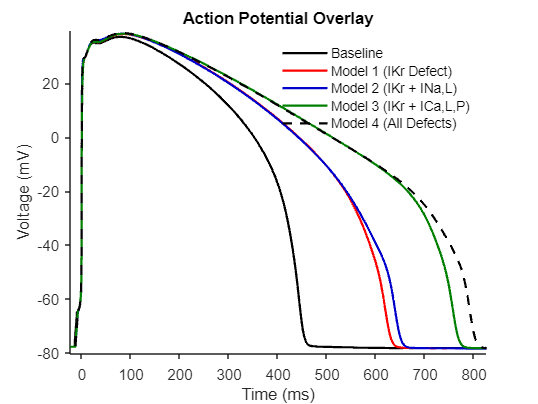

figure('Name', 'AP Morphology Overlays', 'Color', 'w');
hold on;
for i = 1:num_models
    line_style = '-'; if i==5, line_style = '--'; end
    plot(all_time_ap{i}, all_vm{i}, 'Color', colors(i,:), 'LineStyle', line_style, 'LineWidth', 1.5);
end
title('Action Potential Overlay');
xlabel('Time (ms)');
ylabel('Voltage (mV)');
xlim([-50 800]); % Zoom in on the AP
legend(model_legends, 'Location', 'northeast');
legend boxoff;
set(gca, 'box', 'off', 'tickdir', 'out');
hold off;

## FIGURE 7B: Bar Charts for Morphology Stats

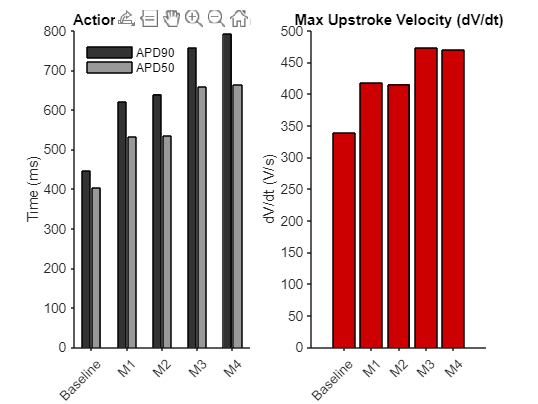

figure('Name', 'AP Parameter Comparison', 'Color', 'w');

% --- Subplot 1: APD90 and APD50 ---
subplot(1, 2, 1);
b = bar(stats_matrix(:, 1:2), 'grouped');
b(1).FaceColor = [0.2 0.2 0.2]; % Dark Grey for APD90
b(2).FaceColor = [0.6 0.6 0.6]; % Light Grey for APD50
title('Action Potential Duration');
ylabel('Time (ms)');
set(gca, 'XTickLabel', {'Baseline', 'M1', 'M2', 'M3', 'M4'});
xtickangle(45);
legend({'APD90', 'APD50'}, 'Location', 'northwest');
legend boxoff;
set(gca, 'box', 'off', 'tickdir', 'out');

% --- Subplot 2: dV/dt Max ---
subplot(1, 2, 2);
b2 = bar(stats_matrix(:, 3));
b2.FaceColor = [0.8 0 0]; % Red for Upstroke
title('Max Upstroke Velocity (dV/dt)');
ylabel('dV/dt (V/s)');
set(gca, 'XTickLabel', {'Baseline', 'M1', 'M2', 'M3', 'M4'});
xtickangle(45);
set(gca, 'box', 'off', 'tickdir', 'out');

## DATA TABLE

fprintf('\n--- Action Potential Morphology Table ---\n');


--- Action Potential Morphology Table ---


% Define headers with new columns
fprintf('%-22s | %-9s | %-9s | %-9s | %-9s | %-9s | %-9s | %-10s\n', ...
    'Model', 'RMP (mV)', 'Vmax (mV)', 'Amp (mV)', 'dV/dt', 'APD30', 'APD50', 'APD90 (ms)');

Model                  | RMP (mV)  | Vmax (mV) | Amp (mV)  | dV/dt     | APD30     | APD50     | APD90 (ms)


fprintf('----------------------------------------------------------------------------------------------------------------\n');

----------------------------------------------------------------------------------------------------------------



for i = 1:num_models
    fprintf('%-22s | %9.1f | %9.1f | %9.1f | %9.1f | %9.1f | %9.1f | %10.1f\n', ...
        model_legends{i}, ...
        stats_matrix(i,7), ... % RMP
        stats_matrix(i,6), ... % Vmax
        stats_matrix(i,5), ... % Amplitude (APA)
        stats_matrix(i,4), ... % dV/dt
        stats_matrix(i,3), ... % APD30
        stats_matrix(i,2), ... % APD50
        stats_matrix(i,1));    % APD90
end

Baseline               |     -75.8 |      37.3 |     113.1 |     110.8 |     338.8 |     403.8 |      446.2
Model 1 (IKr Defect)   |     -75.8 |      38.4 |     114.1 |     116.6 |     417.8 |     533.4 |      619.9
Model 2 (IKr + INa,L)  |     -75.8 |      38.5 |     114.3 |     127.0 |     415.6 |     534.6 |      639.7
Model 3 (IKr + ICa,L,P) |     -75.8 |      38.5 |     114.3 |     116.6 |     472.6 |     657.6 |      757.8
Model 4 (All Defects)  |     -75.8 |      38.7 |     114.5 |     127.0 |     470.1 |     664.2 |      792.0



% ========================================================================
%  HELPER FUNCTION
% ========================================================================

function results = calculate_ap_stats(time, voltage)
% Calculates AP stats for a single beat

% 1. Derivatives for Upstroke
dV = diff(voltage);
dt = diff(time);
dVdt = dV ./ dt; % mV/ms = V/s

[dVdt_max, idx_max_diff] = max(dVdt);
t_depol = time(idx_max_diff);

% 2. Peak Voltage (Search only after upstroke)
[V_max, idx_peak_local] = max(voltage(idx_max_diff:end));
idx_peak = idx_peak_local + idx_max_diff - 1;
t_peak = time(idx_peak);

% 3. Resting Potential (Take mean of first few points before upstroke)
if idx_max_diff > 10
    RMP = mean(voltage(1:10));
else
    RMP = voltage(1);
end

APA = V_max - RMP;

% 4. APD Calculations
% Function to find time at repolarization %
get_apd = @(pct) interp1(voltage(idx_peak:end), time(idx_peak:end), V_max - (pct/100)*APA, 'linear', NaN) - t_depol;

results.APD90 = get_apd(90);
results.APD50 = get_apd(50);
results.APD30 = get_apd(30);  
results.dVdt_max = dVdt_max;
results.APA = APA;
results.RMP = RMP;
results.V_max = V_max;        
results.t_depol = t_depol;
end